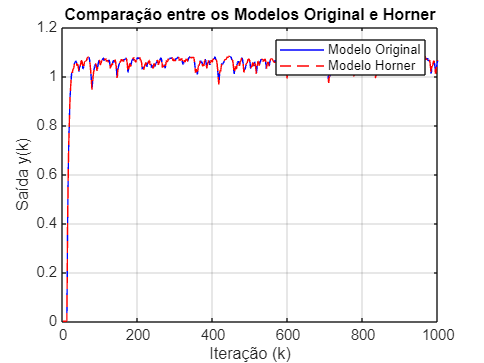

clear all
clc

format long
% Carregar os dados de entrada (u_cc.csv) e saída do sistema físico (y_cc.csv)
u_cc = csvread('u_cc.csv');
y_cc = csvread('y_cc.csv');

% Decimação dos dados
d = 500;
u_cc = downsample(u_cc, d);
y_cc = downsample(y_cc, d);

% Novo tamanho dos dados após decimação
N = length(u_cc);

% Inicializar os vetores de saída para os dois modelos
y_original = zeros(N, 1);
y_horner = zeros(N, 1);

% Iniciar a simulação do modelo original
tic; % Início da contagem de tempo para o modelo original
for k = 3:N
    y_original(k) = 1.7813 * y_original(k-1) - 0.7962 * y_original(k-2) ...
        + 0.0339 * u_cc(k-1) - 0.1597 * u_cc(k-1) * y_original(k-1) ...
        + 0.0338 * u_cc(k-2) + 0.1297 * u_cc(k-1) * y_original(k-2) ...
        - 0.1396 * u_cc(k-2) * y_original(k-1) ...
        + 0.1086 * u_cc(k-2) * y_original(k-2) ...
        + 0.0085 * y_original(k-2)^2;
end
time_original = toc; % Tempo total para o modelo original

% Iniciar a simulação do modelo com Horner
tic; % Início da contagem de tempo para o modelo com Horner
for k = 3:N
    a0 = 1.7813 * y_horner(k-1) + 0.0339 * u_cc(k-1) - 0.1597 * u_cc(k-1) * y_horner(k-1) ...
        + 0.0338 * u_cc(k-2) - 0.1396 * u_cc(k-2) * y_horner(k-1);
    a1 = -0.7962 + 0.1297 * u_cc(k-1) + 0.1086 * u_cc(k-2);
    y_horner(k) = a0 + y_horner(k-2) * (a1 + y_horner(k-2) * 0.0085);
end
time_horner = toc; % Tempo total para o modelo com Horner

% Plotar os resultados das duas simulações
figure;
plot(1:1000, y_original(1:1000), 'b', 'DisplayName', 'Modelo Original');
hold on;
plot(1:1000, y_horner(1:1000), 'r--', 'DisplayName', 'Modelo Horner');
legend('show');
xlabel('Iteração (k)');
ylabel('Saída y(k)');
title('Comparação entre os Modelos Original e Horner');
grid on;


% Calcular o RMSE entre o modelo original e o modelo com Horner
rmse_horner_vs_original = sqrt(mean((y_original - y_horner).^2));

% Exibir os resultados
fprintf('Tempo de simulação do modelo original: %.4f segundos\n', time_original);

Tempo de simulação do modelo original: 0.0117 segundos


fprintf('Tempo de simulação do modelo com Horner: %.4f segundos\n', time_horner);

Tempo de simulação do modelo com Horner: 0.0031 segundos


fprintf('RMSE entre o modelo original e o modelo com Horner: %.4f\n', rmse_horner_vs_original);

RMSE entre o modelo original e o modelo com Horner: 0.0000
